# **ETSMP - CONTINUOUS RANDOM VARIABLES**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

# **INITIALIZATION**

clc
clear

addpath('[0] Library');
Color = load("colors.mat");

# **PROBLEM 2.18**

**Show that the expected value operator has the following properties.**

**A:** $E\left\lbrack a+\mathrm{bX}\right\rbrack =a+b\left\lbrack X\right\rbrack$

**B:** $E\left\lbrack \mathrm{aX}+\mathrm{bY}\right\rbrack =a\cdot E\left\lbrack X\right\rbrack +b\cdot E\left\lbrack Y\right\rbrack$

**C:** $\mathrm{var}\left(\mathrm{aX}+\mathrm{bY}\right)=a^2 \cdot \mathrm{var}\left(X\right)+b^2 \cdot \mathrm{var}\left(Y\right)+2\mathrm{ab}\cdot \mathrm{covar}\left(X,Y\right)$

## [A] ESTIMATED VALUE


$$E\left\lbrack a+b\cdot \;X\right\rbrack =\int a\cdot f_{X\left(x\right)} \;\mathrm{dx}+\int b\cdot x\cdot f_{X\left(x\right)} \;\mathrm{dx}$$



$$E\left\lbrack a+b\cdot X\right\rbrack =a\cdot \int f_{X\left(x\right)} \;\mathrm{dx}+b\cdot \int x\cdot f_{X\left(x\right)} \;\mathrm{dx}$$



$$E\left\lbrack a+b\cdot X\right\rbrack =a+b\cdot E\left\lbrack X\right\rbrack$$


## [B] ESTIMATED VALUE


$$E\left\lbrack a\cdot X+b\cdot Y\right\rbrack =\int a\cdot \;x\cdot f_{X\left(x\right)} \mathrm{dx}+\int b\cdot y\cdot f_{Y\left(y\right)} \;\mathrm{dx}$$



$$E\left\lbrack a\cdot X+b\cdot Y\right\rbrack =a\cdot \int x\cdot f_{X\left(x\right)} \;\mathrm{dx}+b\cdot \int y\cdot f_{Y\left(y\right)} \;\mathrm{dy}$$



$$E\left\lbrack a\cdot X+b\cdot Y\right\rbrack =a\cdot E\left\lbrack X\right\rbrack +b\cdot E\left\lbrack Y\right\rbrack$$


## [C] VARIANCE


$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =E\left\lbrack {\left(aX+bY\right)}^2 \right\rbrack -E{\left\lbrack aX+bY\right\rbrack }^2$$



$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =\int {\left(ax+by\right)}^2 \cdot f_{X,Y\left(x,y\right)} \;dx\;dy-{\left(a\cdot E\left\lbrack X\right\rbrack +b\cdot E\left\lbrack Y\right\rbrack \right)}^2$$



$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =\int \left(a^2 x^2 +b^2 y^2 +2axby\right)\cdot f_{X,Y} \left(x,y\right)\;dx\;dy-{\left(a\cdot E\left\lbrack X\right\rbrack +b\cdot E\left\lbrack Y\right\rbrack \right)}^2$$



$$\begin{array}{l}
\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =a^2 \cdot \int x^2 \cdot f_{X\left(x\right)} \;dx-a^2 \cdot E{\left\lbrack X\right\rbrack }^2 +b^2 \cdot \int y^2 \cdot f_{Y\left(y\right)} \;\mathrm{dy}-b^2 \cdot E{\left\lbrack Y\right\rbrack }^2 +2ab\\
\cdot \int xy\cdot f_{X,Y\left(x,y\right)} \;dx\;dy-2ab\cdot E\left\lbrack X\right\rbrack \cdot E\left\lbrack Y\right\rbrack 
\end{array}$$



$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =a^2 \cdot \left(E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 \right)+b^2 \cdot \left(E\left\lbrack Y^2 \right\rbrack -E{\left\lbrack Y\right\rbrack }^2 \right)+2ab\cdot \mathrm{COVAR}\left\lbrack X,Y\right\rbrack$$



$$\mathrm{VAR}\left\lbrack aX+bY\right\rbrack =a^2 \cdot \mathrm{VAR}\left\lbrack X\right\rbrack +b^2 \cdot \mathrm{VAR}\left\lbrack Y\right\rbrack +2ab\cdot \mathrm{COVAR}\left\lbrack X,Y\right\rbrack$$


# **PROBLEM 2.24**

**X is a Gaussian random variable with **$\mu_x =2$ **and **$\sigma_x^2 =9$. **Find **$P\left(-4<X\le 5\right)$**using tabulated values of **$Q\left(\ldotp \right)$ 

## **[A] PROBABILITY**

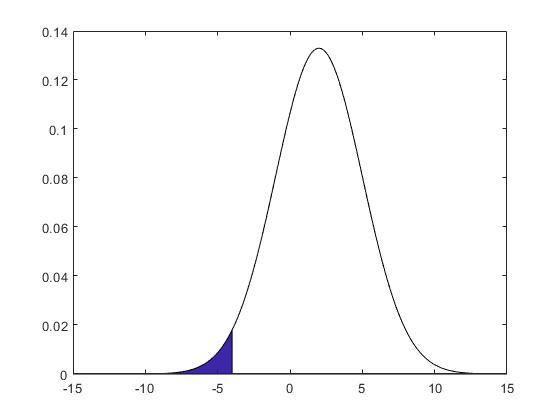

mu = 2;
sigmasquared = 9;
sigma = sqrt(sigmasquared);

x = -15:.1:15;
y = normpdf(x, mu, sigma);

figure(1)
pdfarea(x, y, [], -4);

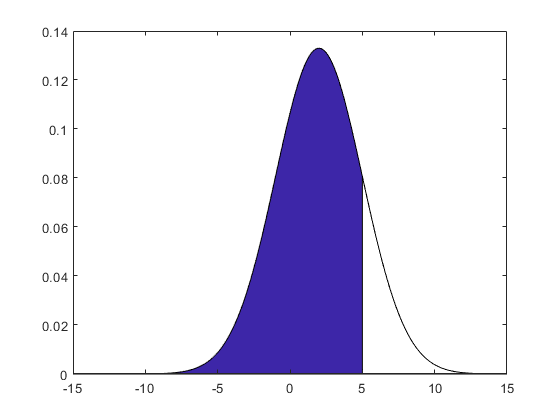


figure(2)
pdfarea(x, y, [], 5);

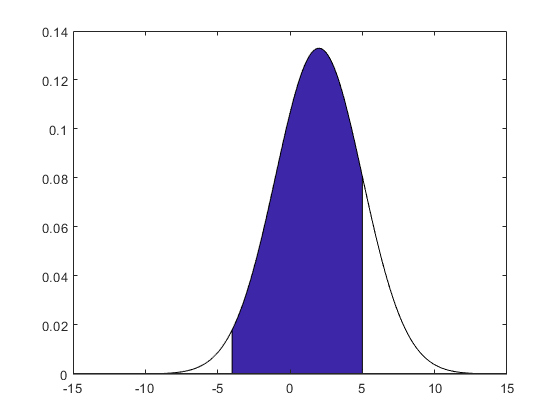


figure(3)
pdfarea(x, y, -4, 5);


LProbability = normcdf(-4, mu, sigma);
HProbability = normcdf(5, mu, sigma);

Probability = HProbability - LProbability;

disp("Probability of value between -4 and 5 is: " + Probability);

Probability of value between -4 and 5 is: 0.81859


# **PROBLEM 2.29**

**The joint pdf of random variables X and Y is**


$$f_{X,Y} \left(x,y\right)=\frac{1}{2},\;0\le \;x\le \;y,\;0\le y\le 2$$


**A:** Find the marginal pdfs, $f_X \left(x\right)$ and $f_Y \left(y\right)\ldotp$

**B:** Find the conditionals pdfs $f_{X|Y} \left(x|y\right)$ and $f_{Y|X} \left(y|x\right)$.

**C: **Find $E\left\lbrace X|Y=1\right\rbrace$ and $E\left\lbrace X|Y=0\ldotp 5\right\rbrace \ldotp$

**D: **Are **X** and **Y** statistically independent?

**E:** Find $\rho_{\mathrm{XY}} \ldotp$

## [A] MARGINAL PDF'S

  
$$f_X \left(x\right)=\int_x^2 f_{X,Y} \left(x,y\right)\;dy$$



$$f_X \left(x\right)=\int_x^2 \frac{1}{2}dy={\left\lbrack \frac{1}{2}\cdot y\right\rbrack }_x^2$$



$$f_X \left(x\right)=1-\frac{1}{2}\cdot x,\;\;\;\;\;0\le x\le 2$$



$$f_Y \left(y\right)=\int_0^y f_{X,Y} \left(x,y\right)\;dx$$



$$f_Y \left(y\right)=\int_0^y \frac{1}{2}dx={\left\lbrack \frac{1}{2}\cdot x\right\rbrack }_0^y$$



$$f_Y \left(y\right)=\frac{1}{2}\cdot y,\;\;\;\;\;0\le y\le 2$$


## [B] CONDITIONAL PDF'S


$$f_{X|Y} \left(x|y\right)=\frac{f_{X,Y} \left(x,y\right)}{f_Y \left(y\right)}$$



$$f_{X|Y} \left(x|y\right)=\frac{\frac{1}{2}}{\frac{1}{2}\cdot y}=\frac{1}{y},\;\;\;0\le x\le y,\;\;\;0\le y\le 2$$



$$f_{Y|X} \left(y|x\right)=\frac{f_{X,Y} \left(x,y\right)}{f_X \left(x\right)}$$



$$f_{Y\left|X\right.} \left(y\left|x\right.\right)=\frac{\frac{1}{2}}{1-\frac{1}{2}x}=\frac{1}{2-x},\;\;\;0\le x\le 2,\;\;\;x\le y\le 2$$


## [C] ESTIMATED VALUES


$$f_{X|Y=1} \left(x|y=1\right)=\frac{1}{1}=1,\;\;0\le x\le 1\;$$



$$E\left\lbrack X|Y=1\right\rbrack =\int x\cdot f_X \left(x\right)\;dx$$



$$E\left\lbrack X\left|Y=1\right.\right\rbrack =\int_0^1 x\cdot 1\;dx={\left\lbrack \frac{1}{2}x^2 \right\rbrack }_0^1$$



$$E\left\lbrack X|Y=1\right\rbrack =\frac{1}{2}\cdot 1^2 =\frac{1}{2}$$



$$f_{X\left|Y=1\right.} \left(x\left|y=1\right.\right)=\frac{1}{0\ldotp 5}=2,\;\;0\le x\le 0\ldotp 5$$



$$E\left\lbrack X\left|Y=0\ldotp 5\right.\right\rbrack =\int x\cdot f_X \left(x\right)\;dx$$



$$E\left\lbrack X\left|Y=1\right.\right\rbrack =\int_0^1 x\cdot 2\;dx={2\cdot \left\lbrack \frac{1}{2}x^2 \right\rbrack }_0^{0\ldotp 5}$$



$$E\left\lbrack X\left|Y=1\right.\right\rbrack =2\cdot \left\lbrack \frac{1}{2}\cdot {0\ldotp 5}^2 \right\rbrack =2\cdot \left\lbrack \frac{1}{2}\cdot \frac{1}{4}\right\rbrack =2\cdot \frac{1}{8}=\frac{2}{8}=\frac{1}{4}$$


## [D] STATISTICALLY INDEPENDENT

No, because


$$f_{X,Y} \left(x,y\right)\not= f_x \left(x\right)\cdot f_y \left(y\right)$$


## [E] CORRELATION COEFFICIENT

# **RESISTOR PRODUCTION**

**In production of 100 ohm resistors, the resistance of each resistors will be a random variable that is Gaussian distributed with a mean of 100 ohm, and a standard deviation of sigma. The resistors are sorted in 5% and 10% resistors. Thus all resistors within 5% of 100 ohm are sorted in one package and resistors between 5% and 10% are sorted in another package. Resistors deviating more than 10% are discarded.**

**A: **Begin by assuming that sigma is equal to 5. How many percent on average of the produced resistors are in each package, and how many is discarded. Instead of a lookup table you can use the matlab function normcdf. Use the doc in matlab to find out arguments in the function.

**B: **Make a matlab simulation that simulate 1000 resistors, and confirm the result obtained in question A. Use matlab randn function.

**C: **What should the standard deviation be if the packages of 5% resistors contains half of the resistors? Find the result with the function norminv.

**D: **Sample 1000 resistors with the found standard deviation. Plot the pdf and cdf with a histogram function in matlab.

**E: **Find the mean and standard deviation of the 1000 samples, use the mean and var functions in matlab.

**F: **Why are the found mean and standard deviation not exact?

## **[A] CUMMULATIVE DISTRIBUTION**

mu = 100;
sigma = 5;
sigma_squared = 5^2;

x = 80:0.1:120

x =    80.0000   80.1000   80.2000   80.3000   80.4000   80.5000   80.6000   80.7000   80.8000   80.9000   81.0000   81.1000   81.2000   81.3000   81.4000   81.5000   81.6000   81.7000   81.8000   81.9000   82.0000   82.1000   82.2000   82.3000   82.4000   82.5000   82.6000   82.7000   82.8000   82.9000   83.0000   83.1000   83.2000   83.3000   83.4000   83.5000   83.6000   83.7000   83.8000   83.9000   84.0000   84.1000   84.2000   84.3000   84.4000   84.5000   84.6000   84.7000   84.8000   84.9000


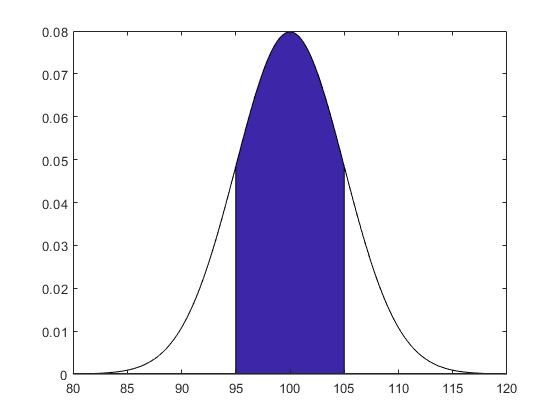

y = normpdf(x, mu, sigma);

probability_above_95 = normcdf(95, mu, sigma);
probability_above_90 = normcdf(90, mu, sigma);

% Probability within 5 percent
probability_5_percent = (1 - 2*probability_above_95) * 100;
pdfarea(x, y, 95, 105);

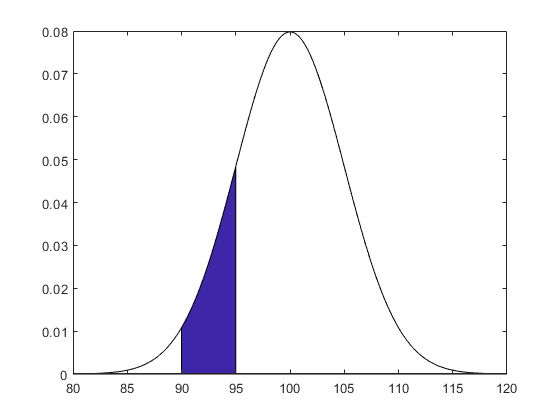


% Probability within 10 percent
probability_10_percent = 2 * (probability_above_95 - probability_above_90) * 100;

figure(4)
pdfarea(x, y, 90, 95);

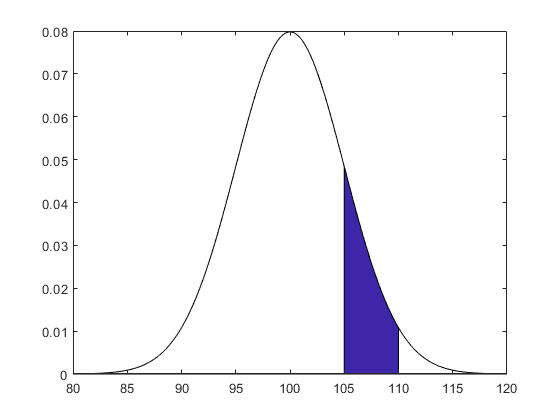


figure(5)
pdfarea(x, y, 105, 110);

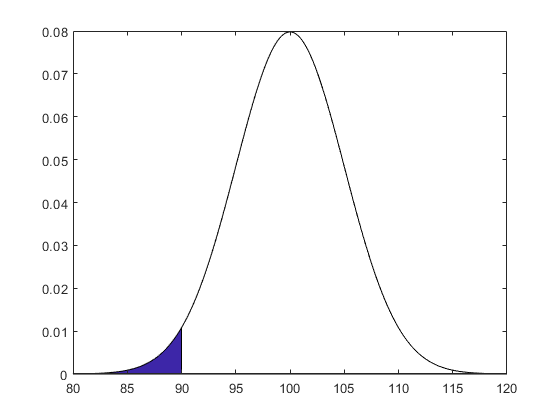


%Probability discarded / above 10 percent
probability_discarded = 2 * probability_above_90 * 100;

figure(6)
pdfarea(x, y, [], 90)

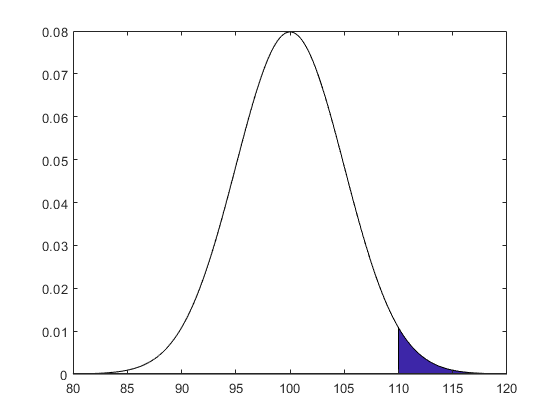


figure(7)
pdfarea(x, y, 110)

## **[B] SIMULATION**

numberOfResistors = 1000;

numberOfDiscardedResistors = 0;
numberOf10PercentResistors = 0;
numberOf5PercentResistors = 0;

mu = 100;
sigma = 5;

resistors = sigma * randn(1, numberOfResistors) + mu;

for x = 1:numberOfResistors
    if resistors(x) > 110 || resistors(x) < 90
        numberOfDiscardedResistors = numberOfDiscardedResistors + 1;
    elseif resistors(x) > 105 || resistors(x) < 95
        numberOf10PercentResistors = numberOf10PercentResistors + 1;
    else
        numberOf5PercentResistors = numberOf5PercentResistors + 1;    
    end
end


numberOf5PercentResistors = (numberOf5PercentResistors * 100) / numberOfResistors;
numberOf10PercentResistors = (numberOf10PercentResistors * 100) / numberOfResistors;
numberOfDiscardedResistors = (numberOfDiscardedResistors * 100) / numberOfResistors;

## [C] STANDARD DEVIATION

sigma = 5;
mu = 100;

for x = 1:10000
    if norminv(0.25, mu, sigma) > 95
        sigma = sigma + 0.001;
    end
end

## [D] PLOT

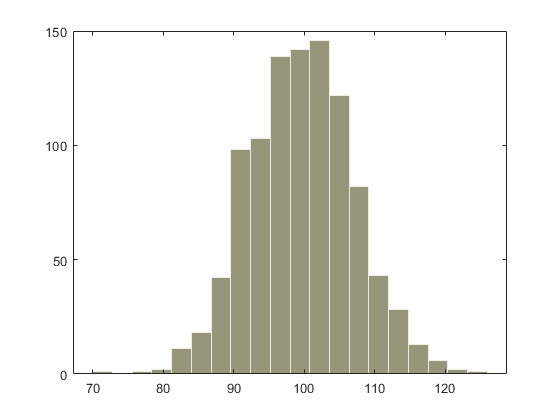

sigma = 7.4140;
mu = 100;
bins = 20;

numberOfResistors = 1000;
resistors = sigma * randn(1, numberOfResistors) + mu;

figure(8)
p = histogram(resistors, bins, 'FaceColor', Color.ArmyGreen, 'EdgeColor', Color.MarshMallow);

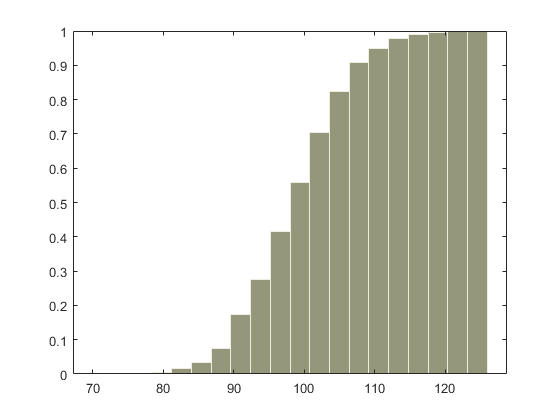


% cdfplot(resistors)

figure(9)
c = histogram(resistors, bins, 'FaceColor', Color.ArmyGreen, 'EdgeColor', Color.MarshMallow, 'Normalization', 'cdf');

## [E] MEAN & STANDARD DEVIATION

resistorMean = mean(resistors);

resistorStdDeviation = sqrt(var(resistors));

## [F] PRECISION

The found value for mean and standard deviation is not exact because the sample size is not big enough.